将文本渲染为二值图像

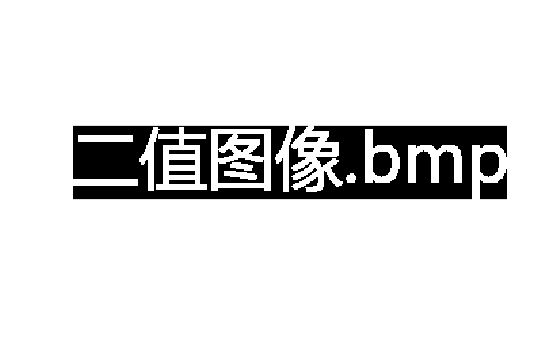

imshow(ComputerVision.TextMask('二值图像.bmp',50));

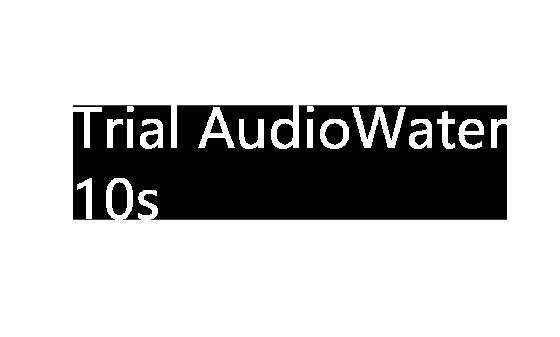


%支持多行文本
imshow(ComputerVision.TextMask("Trial AudioWater"+newline+"10s",100));

绘制条形图和P值线

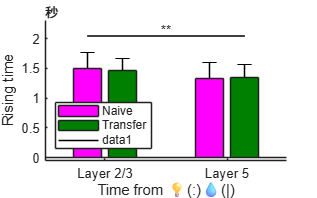

load('+MATLAB\+Graphics\PLine.mat');
figure;
Bars=bar(ActiveLightRising{["MOp2/3","MOp5"],["NaiveLight","Transfer"],"Mean"});
colororder([1,0,1;0,0.5,0]);
MATLAB.Graphics.FigureAspectRatio(8,5,1/3);
Ax=gca;
Ax.Units='points';
hold on;
EBs=errorbar(vertcat(Bars.XEndPoints).',ActiveLightRising{["MOp2/3","MOp5"],["NaiveLight","Transfer"],"Mean"},[],ActiveLightRising{["MOp2/3","MOp5"],["NaiveLight","Transfer"],"Sem"},CapSize=Ax.Position(3)*Bars(1).GroupWidth*Bars(1).BarWidth/(numel(Bars)*diff(xlim)*2),Color='k',LineStyle='none');
xticks(1:2);
xticklabels(["Layer 2/3","Layer 5"]);
box off;
xlabel('Time from 💡(:)💧(|)');
ylim([0,diff(ylim)]);
ylabel('Rising time');
legend(Bars,["Naive","Transfer"],Location=MATLAB.Graphics.OptimizedLegendLocation(Bars));
ComputerVision.PLine(table(EBs(1),EBs(end),1,2,"**",'VariableNames',["ObjectA","ObjectB","IndexA","IndexB","Text"]),0.1);